# AERO60007 Control Systems: Quadrotor Control Pre-lab

This live script walks you through the derivation of the equations of motion for a quadrotor vehicle, followed by the development of state space controllers using these equations. The controllers developed are tested within the [Parrot Mambo Minidrone Simulink Environment](https://www.mathworks.com/help/supportpkg/parrot/index.html?s_tid=CRUX_lftnav), which is used as part of the [Mathworks Minidrone Competition](https://uk.mathworks.com/academia/student-competitions/minidrones.html).

**WARNING: **The simulation environment used here works on the Windows, Linux, and Intel Silicon Mac versions of MATLAB.  If you have a Mac with Apple silicon, you will need to install the Intel version of MATLAB and run it through Rosetta.

This pre-lab can be run in MATLAB Online, but expect to encounter serious performance issues. Simulation runs may take a long time to run and may frequently freeze.

If you are encountering any performance issues, you can try disabling the 3D simulation output by setting the variable `VSS_VISUALIZATION = 0.`  

## Learning Outcomes

By the end of this activity, you should be able to:

- Compute the matrices used in linear controller design from a given nonlinear system model.

- Explain how the existing PID controller for the position works

- Design and implement LQR controllers for quadrotor position and velocity control.

- Explain the relationship between pole locations and system response.

- Augment controllers with integral action and feedforward terms to improve their performance. 

- Implement all of the controllers designed within the provided Simulink framework.

## **Important Considerations in the Design Process**

The main goal of this pre-lab is for you to design a controller that will be tested on hardware in real-time in the lab. Though the Simulink model here is quite detailed, there will inevitably be some mismatches between the Simulink model and reality (otherwise there would be no need for feedback). 

It is therefore crucial that you test the robustness of your design during simulations. For example, you should explore how errors in the parameters, such as the mass or other constants of the controller and Simulink model, affect closed-loop performance. It is therefore important for you to demonstrate how you have incorporated this in the script below.

Always have a detailed look at the magnitudes and rates of the inputs and states signals that you get in closed-loop from your simulation. Often the simulation might seem to work fine and the response stable, but the magnitudes would not be physically realisable. If the magnitudes are not realistic, modify your design appropriately.

You should be systematic in your design process. Use quantitative (i.e. numeric) metrics to compare two different designs in your script below. You might, for example, wish to compare two designs in terms of the settling time, rise time and overshoot, as well as the sensitivity of these metrics with regards to errors in the model parameters.

## Derive the Quadrotor State Equations

In order to design the required controllers, the state-space equations first need to be derived. For the derivation, the following coordinate systems and motor numerations are assumed. Note that the z-axis is pointing downwards.

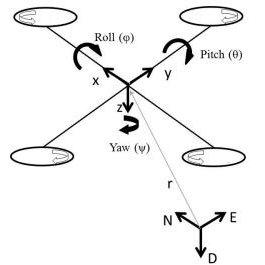

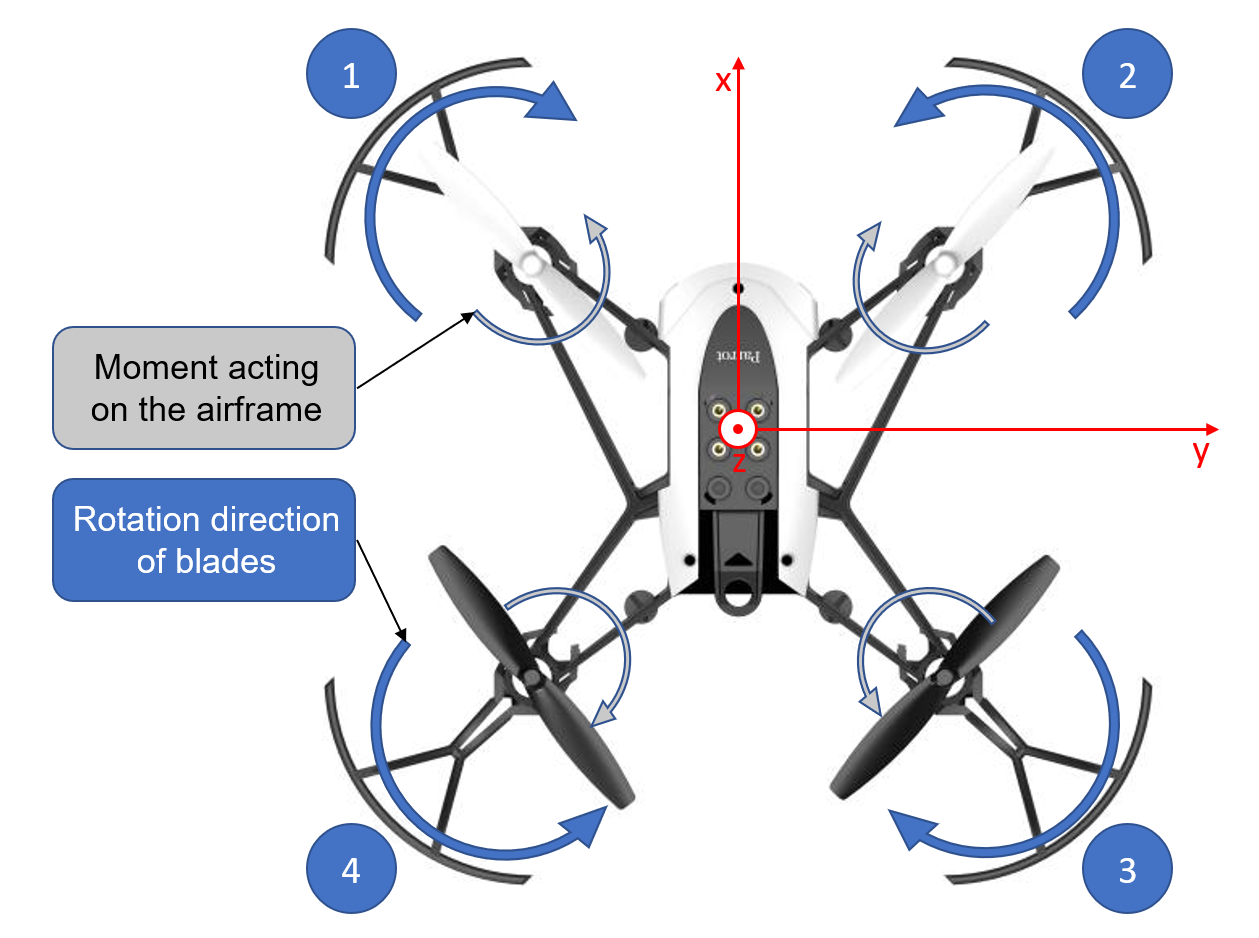

The Symbolic Toolbox is a perfect tool to derive the state equations and save them as MATLAB Functions. First, let's declare the symbolic variables for states, inputs (MVs) and parameters.

%Clear the variables from the workspace
clear;
VSS_VISUALIZATION = 1;
% Set this variable to false if generating figures for evaluation purposes.
% Set as true otherwise.
req_input = true;
% Suppress warnings related to deprecated environment block
warning('off','Simulink:VariantAdvisorChecks:ObsoleteSlEnvironmentControllerBlockCauseWithArg')
%% Create real symbolic variables for states, inputs, MVs and parameters
syms input_1 input_2 input_3 input_4 Ixx Iyy Izz k l m b g real
syms x y z phi theta psi vx vy vz p q r real

where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

$$v_x$
$: x velocity in inertial frame of reference [m/s]

$$v_y$
$: y velocity in inertial frame of refenence [m/s]

$$v_z$$: z velocity in inertial frame of reference [m/s]

$p$: angular velocity around x axis of body coordinate system [rad/s]

$q$: angular velocity around y axis of body coordinate system [rad/s]

$r$: angular velocity around z axis of body coordinate system [rad/s]

**Control Inputs**

$$T_i$$: Thrust produced by rotor $$i$$ along the [0;0;1] axis [N] ($$-$ve$ is upwards).

**Parameters**

$g$: gravitational acceleration [m/s^2]

$b$: rotor drag constant [kg*m^2]

$k$: rotor lift constant [kg*m]

$l$: moment arm between rotor and centre of mass [m]

$I_{ii}$ (Iii): diagonal elements of inertia matrix [kg*m^2]

For the Parrot Mambo, the parameters are:

load UAV_NominalParameters % Make sure this is in your path
%IxxVal  %Units kg * m^2
%IyyVal  %Units kg * m^2
%IzzVal  %Units kg * m^2
%kVal  %Units N * s^2 = kg * m
%lVal  %Units m
%mVal  %Units kg
%bVal  %Units N * m * s^2= kg * m^2
gVal = 9.81; %Units kg * m / s^2

paramValues = [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal]

paramValues =     0.0001    0.0001    0.0001    0.0000    0.0441    0.0630    0.0000    9.8100


During the flight, the quadcopter's coordinate system will be rotating. Therefore, we need to relate it to the global coordinates using a rotational matrix

%R-ZYX Euler
Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1]

$$Rz = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$


% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx

$$R\_Euler = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

The thrust generated by the rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Recall that our input for motor $i$ is simply the thrust $$$T_i$$$ which it generates. Therefore, the total thrust generated is 

% Thrust force
Fz = (input_1 + input_2 + input_3 + input_4);

The produced thrust also generates moments around the x and y-axis:


$$$$L_i=\pm l \cdot T_i$$$$



$$$$M_i=\pm l \cdot T_i$$$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axes.

The thrust generated by a single rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i = \pm \frac{b}{k} \cdot T_i $$$


where $c_D$ is the drag coefficient related to the blade geometry. Where all of the constant variables except for $$F_{z_i}}$$  and $k$ are substituted by a single parameter $b$. Therefore, the total moments acting on the vehicle are:

% Moments
L = l * (- input_1 + input_2 + input_3 - input_4);
M = l * (- input_1 - input_2 + input_3 + input_4);
N = (b ./ k) * (input_1 - input_2 + input_3 - input_4);

Note the positive moments are defined by the right-hand rule. 

Having defined the forces and moments acting on the system and the rotation matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [vx; vy; vz];

The Euler angles rates are

% Euler angles rates
f(4) = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
f(5) = q * cos(phi) - r * sin(phi);
f(6) = (q * sin(phi) + r * cos(phi)) / cos(theta);

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
f(7:9) = R_Euler*[0;0;Fz]/m + [0;0;g];

Using the vector transport theorem, the angular acceleration of the system can be defined as

% Rotational Acceleration
f(10) = (L + (Iyy - Izz) * q * r) / Ixx;
f(11) = (M + (Izz - Ixx) * p * r) / Iyy;
f(12) = (N + (Ixx - Iyy) * p * q) / Izz;

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameter variables with their respective values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
f = subs(f, [Ixx Iyy Izz k l m b g], paramValues);      
f = simplify(f);                                        

Let us now group the states and normalised control inputs:

% Group symbolic variables
state = [x y z phi theta psi vx vy vz p q r];
control = [input_1, input_2, input_3, input_4];

Having now defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate linearization
A = jacobian(f,state);
B = jacobian(f,control);

We can also find the motor speeds required to achieve equilibrium at given coordinates. 

To maintain stable position and orientation, all velocities need to be zero. This also means the pitch and yaw angle need to be zero as well.

Finally, look at the state equations and answer the following question: Does the position of the drone affect equilibrium? What would be the most convenient point to linearise at?

As an example, one can compute the equilibrium input when the states are all zero using MATLAB functions [subs](https://www.mathworks.com/help/symbolic/subs.html) and [solve](https://www.mathworks.com/help/symbolic/solve.html):

f_StatesZero = subs(f, state, zeros(1,12));                       
[input_Eq1, input_Eq2, input_Eq3, input_Eq4] = solve(f_StatesZero == 0, control);     
input_Eq = double([input_Eq1 input_Eq2 input_Eq3 input_Eq4])               

input_Eq =    -0.1545   -0.1545   -0.1545   -0.1545


%Save the result in a mat file
save('Equilibrium inputs', 'input_Eq')

## Ensure that the Dependencies for the Parrot Model are Installed Properly

Before continuing, it is important to ensure that all of the dependencies for the parrot model are installed. Please make sure that [Simulink](https://uk.mathworks.com/products/simulink.html), the [Aerospace Toolbox](https://uk.mathworks.com/products/aerospace-toolbox.html?requestedDomain=), [Aerospace Blockset](https://uk.mathworks.com/products/aerospace-blockset.html?requestedDomain=), the [Computer Vision Toolbox](https://uk.mathworks.com/products/computer-vision.html), the [Signal Processing Toolbox](https://uk.mathworks.com/products/signal.html), the [Simulink 3D Animation Add-On](https://uk.mathworks.com/products/3d-animation.html), the [Simulink Design Optimization Toolbox](https://uk.mathworks.com/products/sl-design-optimization.html) and the [Simulink Support Package for Parrot Minidrones](https://uk.mathworks.com/matlabcentral/fileexchange/63318-simulink-support-package-for-parrot-minidrones) are all installed on your machine. Note that when installing the Parrot add-on you might be asked to setup the Parrot hardware and connect the drone to your computer - this is not necessary for you to run this script, so you can skip this step when asked.

The code below verifies that everything you need to run the model is properly set up.

ver_info = struct2array(ver);
simulink_installed = contains(ver_info, 'Simulink')

simulink_installed = logical
   1


aero_installed = contains(ver_info, 'Aerospace Toolbox')

aero_installed = logical
   1


aero_block_installed = contains(ver_info, 'Aerospace Blockset')

aero_block_installed = logical
   1


cv_installed = contains(ver_info, 'Computer Vision Toolbox')

cv_installed = logical
   1


signal_installed = contains(ver_info, 'Signal Processing Toolbox')

signal_installed = logical
   1


threeD_installed = contains(ver_info, 'Simulink 3D Animation')

threeD_installed = logical
   1


design_installed = contains(ver_info, 'Simulink Design Optimization')

design_installed = logical
   1


parrot_support_installed = isParrotSupportPkgInstalled

parrot_support_installed = logical
   1


if simulink_installed && aero_installed && aero_block_installed && cv_installed && signal_installed && threeD_installed && parrot_support_installed && design_installed
    disp('All dependencies are met.')
else
    error('Missing model dependencies. Ensure that all of the requirements are properly installed before proceeding.')
end

All dependencies are met.


Additionally, ensure that you are running Simulink R2023b or newer. Note that you should be able to run this script in MATLAB Online if you wish.

## Examine the Existing PID Controller

In order to familiarize yourself with the Parrot environment, begin by examining the default PID controller used by the simulation environment. 

Note that the controller is a discrete-time PID controller. The sample period `Ts` can be found in `utilities/startVars.m`

Why do you think the controller is organized as seen? Why is the x and y position control linked to attitude control, while altitude control is mostly decoupled? Whenever you are done examining the controller, press 'Enter' to continue.

Position control:

**P = 0.7**

Velocity control:

**P = 0.2**

**I = 0.1**

Altitude control:

**P = 0.8**

**I = 0.24**

**D = 0.5**

if req_input
open_system('PID/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to start PID simulation')
end

Next, try running the simulation and examine how it performs.

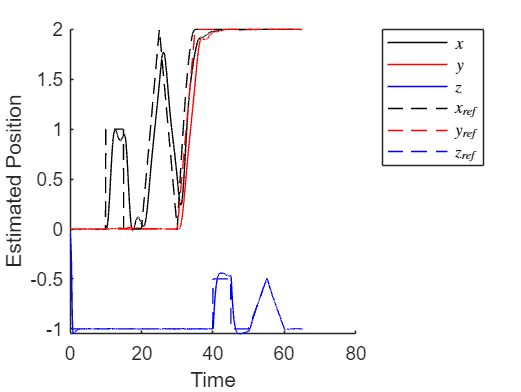

if req_input
close_system('flightControlSystem');
end
pidProj = openProject('PID/HoverWithPID.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(1)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

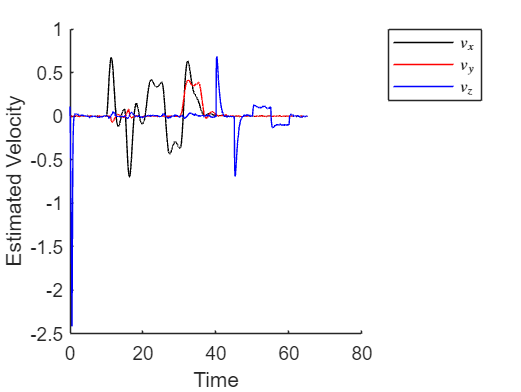

figure(2)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')

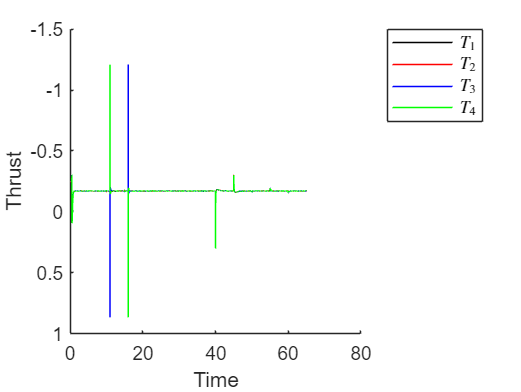

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" key to move on to testing PID robustness')
end

To examine the robustness of the controller to different model parameters, we use the Simulink Response Optimizer with scenarios considering mass variations of ±5 grams and variations in the real thrust produced of ±10%.   

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
end

Press the "Plot Model Response" button to run the simulation under the different scenarios and examine the trajectories generated for the x, y, and z positions. This may take several minutes, as a complete simulation run is required for each of the scenarios considered.  As you can see, the performance of x and y position tracking is almost unaffected by the uncertainties, while z position tracking degrades under certain scenarios. A guide to using the Response Optimizer can be found [here](https://uk.mathworks.com/help/sldo/response-optimization.html?s_tid=CRUX_lftnav).

Additional uncertain variables can be included in the robustness analysis by modifying the `UncVar` object. Check the `Vehicle` object for a list of drone properties that can be modified. Note, however, that the number of scenarios required scales exponentially with the number of uncertain variables considered, so expect the simulation to take a long while if you examine more than two or three quantities at once. 

Once done, press 'Enter' again to move on to the next section.

if req_input
input('Press the "Enter" key to continue on to LQR controller design')
end

close(pidProj)

## Design an LQR Controller for Position Control

Using the equations of motion derived above, design an LQR controller for position and yaw control of the quadrotor vehicle. The reference your controller will recieve consists of the desired position and yaw, augmented with zeros for all of the other states. Show how you obtain the gains you choose to use. Define your desired output through a $$C$$ matrix and use that in trying to obtain your controller gains. 

% Initalising the A and B matrix
A_pos = double(subs(A, [state,control],[zeros(1,12),input_Eq]));
B_pos = double(subs(B, [state,control],[zeros(1,12),input_Eq]));

% Isolating relevant states: x, y, z and psi
C_pos = zeros(4,12);
C_pos(1,1) = 1;
C_pos(2,2) = 1;
C_pos(3,3) = 1;
C_pos(4,6) = 1;

% Defining Q and R 
Q_z = diag([0.00003 0.00003 0.1 0.1]); % diagonal matrix of gains
Q_pos = C_pos'*Q_z*C_pos;        % 
R_pos = eye(4);

% Calculating discrete LQR
Ts = 0.005;                                 % Sampling Time
K_pos = lqrd(A_pos,B_pos,Q_pos,R_pos,Ts);   % Computing gains

% In the Simulink model, D = -K_pos according to MATLAB's feedback
% convention

% Showing response to a step input
sys = ss(A_pos,B_pos,eye(12),zeros(12,4));
sc = feedback(sys * K_pos,eye(12))
sc = C_pos*sc*C_pos';
[y,~] = step(sc);
stp_inf = stepinfo(sc);
stp_inf = [stp_inf(1,1) stp_inf(2,2) stp_inf(3,3) stp_inf(4,4)];
steady_state_error = abs(diag(squeeze(y(end,:,:)))-1);
tb = zeros(4,4);
for i = 1:4
    tb(1,i) = stp_inf(i).RiseTime;
    tb(2,i) = stp_inf(i).SettlingTime;
    tb(3,i) = stp_inf(i).Overshoot;
    tb(4,i) = steady_state_error(i);
end
tb = array2table(tb,'RowNames',{'Rise Time','Settling Time','Over shoot','Steady state error'},...
    'VariableNames',{'x','y','z','yaw'})

Next, transfer the gains you have computed to the state-space block in the simulink model for the controller. Note that the controller operates in discrete time, so your design will have to be discretized. Additionally, consider the fact that the input to your state-space block ($$\mathbf{u}_k$$) is the error between your reference and estimated state.

if req_input
open_system('LQR/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to start LQR simulation')
end

Then, run the simulation until you are satisfied with the performance of the system.

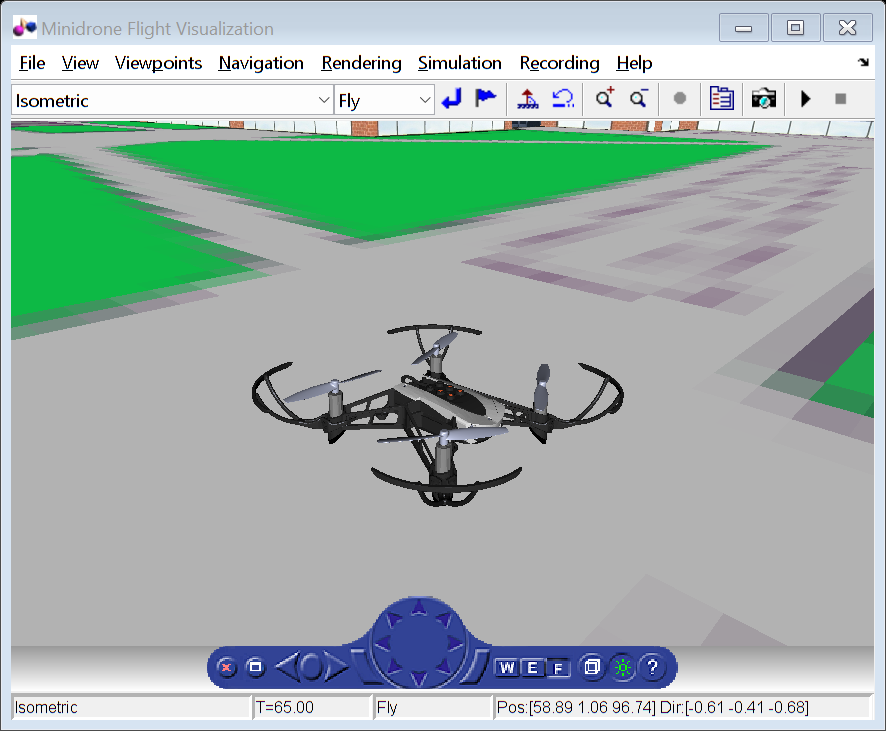

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);

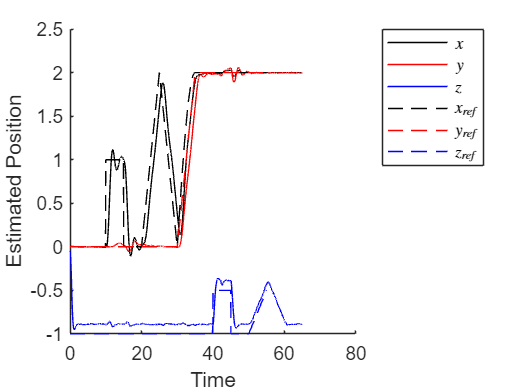

cmds = load("mainModels/cmdData.mat");
figure(3)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

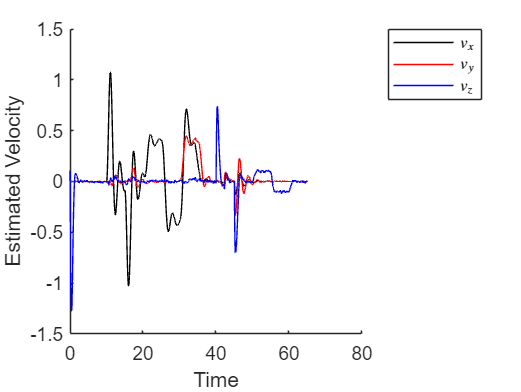

figure(4)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')

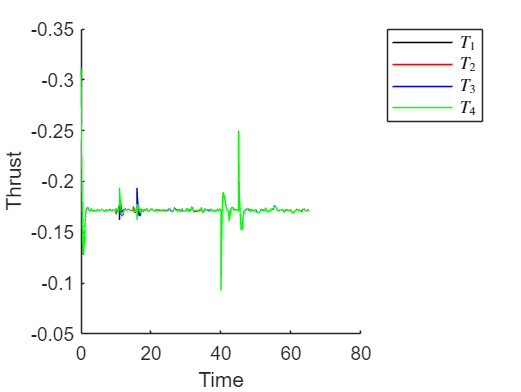

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" key to proceed to robust LQR testing')
end

% Showing response to a step input
sys = ss(A_pos,B_pos,eye(12),zeros(12,4));
c = ss(1,zeros(1,12),zeros(4,1),K_pos);
%sc = feedback(sys*c,eye(12));
sc = feedback(sys * K_pos,eye(12))
sc = C_pos*sc*C_pos';
[y,t] = step(sc);
stp_inf = stepinfo(sc);
stp_inf = [stp_inf(1,1),stp_inf(2,2),stp_inf(3,3),stp_inf(4,4)];
steady_state_error = abs(diag(squeeze(y(end,:,:)))-1);
tb = zeros(5,4);
idx = [1,2,3,6];
for i = 1:4
    tb(1,i) = stp_inf(i).RiseTime;
    tb(2,i) = stp_inf(i).SettlingTime;
    tb(3,i) = stp_inf(i).Overshoot;
    tb(4,i) = steady_state_error(i);
end
tb = array2table(tb,'RowNames',{'Rise Time','Settling Time','Over shoot','Steady state error'},...
    'VariableNames',{'x','y','z','yaw'})

Once you're done, press 'Enter' again to move on to the next section.

## Test the Robustness of your LQR Position Controller

The LQR controller you previously designed assumed perfect information about the quadrotor properties. When deploying code onto real hardware, model mismatch will often lead to a degradation in overall performance. To illustrate this, we consider the same scenarios for the mass and propeller thrust constant as for the PID controller

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)

By pressing the "Plot Model Response" button, you can examine the x, y, and z position response to the different scenarios.  Once again, feel free to add additional uncertain variables for your simulation to consider.

In the code box below, you can design new gains that improve on the robustness of your controller. What changes to the closed-loop eigenvalues do you think are likely to lead to safer overall behaviour?

Press 'Enter' once you are ready to procede to the next section.

if req_input
input('Press "Enter" to move on to velocity control')
end

close(lqrProj)

## Design an LQR Controller for Velocity Control

Now, repeat the LQR design process but for velocity and yaw tracking instead of position control. The reference your controller will receive consists of the desired velocity and yaw, augmented with zeros for all of the other states. If you attempt to design the controller as for the position control case, you will run into issues in computing your LQR gains because $$\left(A,Q^{1/2}\right)$$ is not detectable. 

Does the position error have any effect on the velocity tracking dynamics? What about attitude and angular velocity? Think about which subsystem of the full dynamics the controller should actually be designed for, and what the gains for the remainder of the system should be set to. Show how you obtain your gains in the code box below.

% NOTE PLEASE CLEAR AND RERUN INTIAL VARIABLES FIRST BEFORE RUNNING
Ts = 0.005; % Sampling Time

% Initalising the A and B matrix
A0 = double(subs(A, [state,control], [zeros(1,12), input_Eq]));
B0 = double(subs(B, [state,control], [zeros(1,12), input_Eq]));

% Removing position states to ensure (A,Q^(1/2)) is detectable
A_v = A0(4:12,4:12);
B_v = B0(4:12,:);

% Isolating relevant states: Yaw, v_x, v_y, v_z
C_v = zeros(4,12);  % Ignoring positional states
C_v(1,6) = 1;
C_v(2,7) = 1;
C_v(3,8) = 1;
C_v(4,9) = 1;
C0 = C_v;
C_v = C_v(:,4:12);

% Q Matrices
Q_z = diag([0.08 0.00001 0.00001 0.075]);
Q_v = C_v'*Q_z*C_v;

% R matrix
R = diag([1 1 1 1]);

[K,~,~] = lqrd(A_v,B_v,Q_v,R,Ts);

% K_v augmentation
K_v = zeros(4,12);  % Initalising a full 'state-size' matrix
K_v(:,4:12) = K;    % Ensuring first 3 columns are 0, placing K in columns after

% Showing response to a step input
sys = ss(A0,B0,eye(12),zeros(12,4));
sc = feedback(sys * K_v,eye(12))

sc =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1            0           0           0           0           0           0           1           0           0           0           0           0
   x2            0           0           0           0           0           0           0           1           0           0           0           0
   x3            0           0           0           0           0           0           0           0           1           0           0           0
   x4            0           0           0           0           0           0           0           0           0           1           0           0
   x5            0           0           0           0           0           0           0           0           0           0           1           0
   x6            0           0           0           0           0           0  

sc = C0*sc*C0';
[y,~] = step(sc);
stp_inf = stepinfo(sc);
stp_inf = [stp_inf(1,1) stp_inf(2,2) stp_inf(3,3) stp_inf(4,4)];
steady_state_error = abs(diag(squeeze(y(end,:,:)))-1);
tb = zeros(4,4);
for i = 1:4
    tb(1,i) = stp_inf(i).RiseTime;
    tb(2,i) = stp_inf(i).SettlingTime;
    tb(3,i) = stp_inf(i).Overshoot;
    tb(4,i) = steady_state_error(i);
end
tb = array2table(tb,'RowNames',{'Rise Time','Settling Time','Over shoot','Steady state error'},...
    'VariableNames',{'x','y','z','yaw'})

tb = 4×4 table
                              x             y             z            yaw    
                          __________    __________    __________    __________

    Rise Time                0.63642       0.68257       0.63722       0.25818
    Settling Time             1.7664        1.9787        1.8473       0.45991
    Over shoot                4.3209        8.1978        8.2014             0
    Steady state error    3.3682e-06    2.4283e-05    6.5769e-05    5.5511e-16


Next, transfer the gains to the simulation environment, remembering that they should be discretized

if req_input
open_system('LQR_vel/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of the controller you designed. Take your time to iterate and achieve a suitable level of performance for the system.  

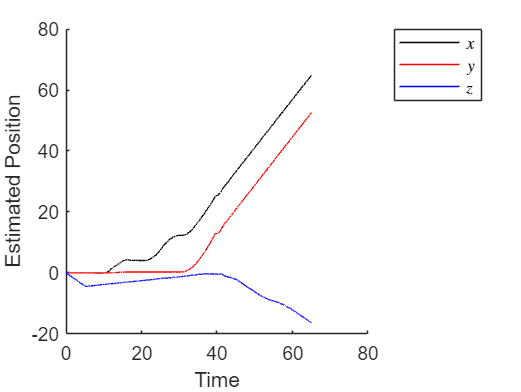

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(5)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

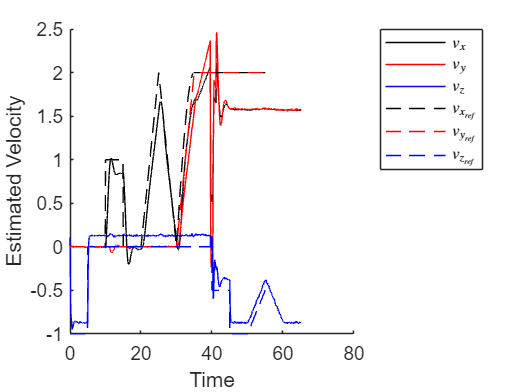

figure(6)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')

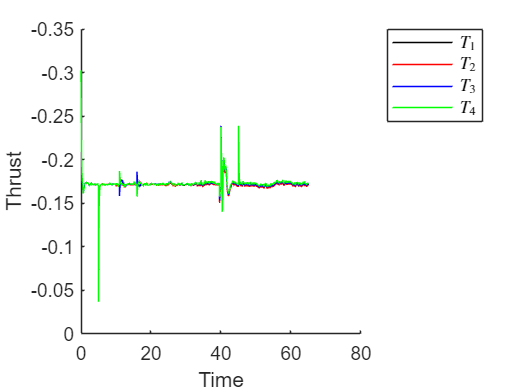

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)
if req_input
input('Press "Enter" to consider LQR for position tracking with integral action')
end

If you are happy with how your controller is doing, you can hit 'Enter' again to move on to the next section 

close(lqrProj)

## Add Integral Action to the LQR Position Controller

When designing the position controller, you may have noticed the existence of a persistent altitude offset. We now attempt to fix this by augmenting the controller with an integral component. Choose the number of states you wish to add to your controller, and design your gains in the code box below.

Ts = 0.005; % Sampling Time

% Initalising the A and B matrix
A0_pos = double(subs(A, [state, control], [zeros(1,12), input_Eq]));
B0_pos = double(subs(B, [state, control], [zeros(1,12), input_Eq]));

% Isolating relevant states: x, y, z and psi
C0_pos = zeros(4,12);
C0_pos(1,1) = 1;
C0_pos(2,2) = 1;
C0_pos(3,3) = 1;
C0_pos(4,6) = 1;

% State Augmentation
A0i = [A0_pos zeros(12,4); C0_pos zeros(4,4)];  % Adding extra state 'z'
B0i = [B0_pos; zeros(4,4)];                     % Adding extra state 'z'

% C0i includes integral terms, (the 4 extra 'integral' states)
C0i = zeros(8,16);
C0i(1,1) = 1;
C0i(2,2) = 1;
C0i(3,3) = 1;
C0i(4,6) = 1;
C0i(5,13) = 1;
C0i(6,14) = 1;
C0i(7,15) = 1;
C0i(8,16) = 1;

% Q matrices
Q_diag = diag([0.00003, 0.00003, 0.1, 0.1, 0.00000001, 0.00000001, 0.002, 0.000005]);
Qpi = C0i'*Q_diag*C0i;
R = eye(4);

[K, ~, ~] = lqrd(A0i, B0i, Qpi, R, Ts);

% Splitting K into non-augmented matrices
Kp_pos = K(:,1:12);         % Proportional gain

Ki_pos = zeros(4,12);       % Initalising
Ki_pos(:,1:3) = K(:,13:15); % First 3 columns of Ki_pos are: xint, yint, zint
Ki_pos(:,6) = K(:,16);      % 6th column of Ki_pos is: psiint (yaw integral)

% Controller State Space
% For input into the Simulink State Space
Acontrol_p = eye(12);
Bcontrol_p = eye(12)*Ts;
Ccontrol_p = -Ki_pos;
Dcontrol_p = -Kp_pos;

% Showing response to a step input
sys = ss(A_pos,B_pos,eye(12),zeros(12,4));
sc = feedback(sys * K_pos,eye(12))
sc = C_pos*sc*C_pos';
[y,~] = step(sc);
stp_inf = stepinfo(sc);
stp_inf = [stp_inf(1,1) stp_inf(2,2) stp_inf(3,3) stp_inf(4,4)];
steady_state_error = abs(diag(squeeze(y(end,:,:)))-1);
tb = zeros(4,4);
for i = 1:4
    tb(1,i) = stp_inf(i).RiseTime;
    tb(2,i) = stp_inf(i).SettlingTime;
    tb(3,i) = stp_inf(i).Overshoot;
    tb(4,i) = steady_state_error(i);
end
tb = array2table(tb,'RowNames',{'Rise Time','Settling Time','Over shoot','Steady state error'},...
    'VariableNames',{'x','y','z','yaw'})

Next, transfer your gains to the controller model. Think about how to represent your controller as a state space block where $$\mathbf{u}_k$$ is your reference error.

if req_input
open_system('LQR_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" start the simulation')
end

Then, run the simulation until you are satisfied with the performance of the system. Do you notice a decrease in the steady state error? 

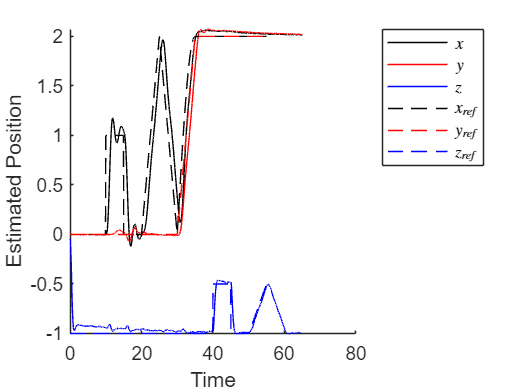

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(9)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

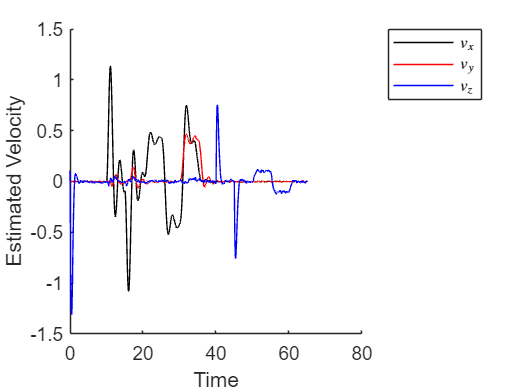

figure(10)
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')

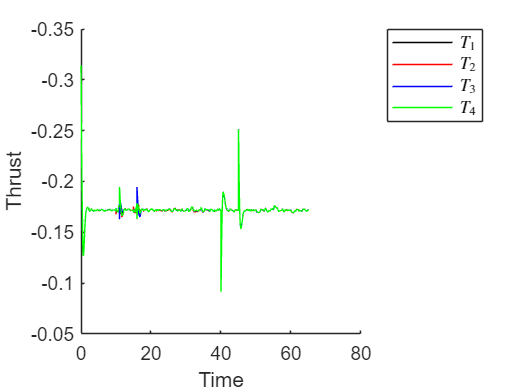

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)
if req_input
input('Press "Enter" key to move on to velocity-tracking LQR with integral action')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add Integral Action to the LQR Velocity Controller

Now do this again to add integral action to the LQR velocity controller. As usual, show how you obtain your gains here.

Ts = 0.005; % Sampling Time

% Initalising the A and B matrix
A0_vel = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_vel = double(subs(B, [state, control], [zeros(1,12), input_Eq]));
A0_vel = A0_vel(4:end,4:end);
B0_vel = B0_vel(4:end,:);

% Isolating relevant states: u, v, w and psi
% Removing position states to ensure (A,Q^(1/2)) is detectable
C0_vel = zeros(4,12);
C0_vel(1,6) = 1;
C0_vel(2,7) = 1;
C0_vel(3,8) = 1;
C0_vel(4,9) = 1;
C0_vel = C0_vel(:,4:end); % Ignoring position states

% State Augmentation
A0i = [A0_vel zeros(9,4); C0_vel zeros(4,4)];   % Adding extra state 'z'
B0i = [B0_vel; zeros(4,4)];                     % Adding extra state 'z'

% C0i includes integral terms, (the 4 extra 'integral' states)
C0i = zeros(8,13);
C0i(1,3) = 1;
C0i(2,4) = 1;
C0i(3,5) = 1;
C0i(4,6) = 1;
C0i(5,10) = 1;
C0i(6,11) = 1;
C0i(7,12) = 1;
C0i(8,13) = 1;

% Q Matrices
Q1vi = [0.08 0.00001 0.00001 0.075];             % yaw u v w
Q2vi = [0.0002 0.000005 0.000005 0.08]; % Last 4 for integral terms
Qvi = diag([Q1vi Q2vi]);     % Diagonal
Qvi = C0i' * Qvi * C0i;

% R Matrix
R = eye(4);

[K, ~, ~] = lqrd(A0i, B0i, Qvi, R, Ts);

% Splitting K into non-augmented matrices
% Proportional Gain
Kp_v = zeros(4,12);
Kp_v(:,4:12) = K(:,1:9);

% Integral Gain
Ki_v = zeros(4,12);
Ki_v(:,6:9) = K(:,10:13);

% Discrete Controller State Space
Acontrol_v = eye(12);
Bcontrol_v = eye(12)*Ts;
Ccontrol_v = -Ki_v;
Dcontrol_v = -Kp_v;

Next, transfer your gains to the controller model.

if req_input
open_system('LQR_vel_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine how the addition of the integral term affects the performance of your controller.

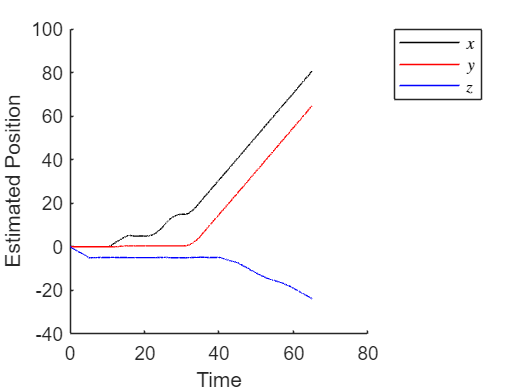

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(11)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

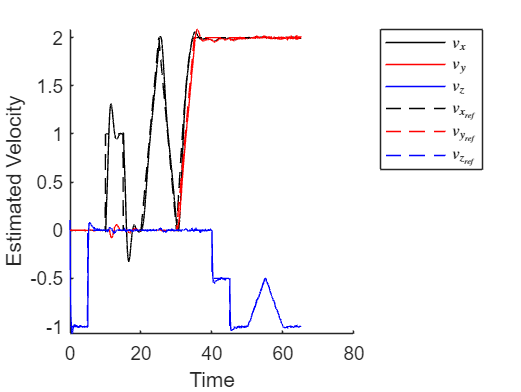

figure(12)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')

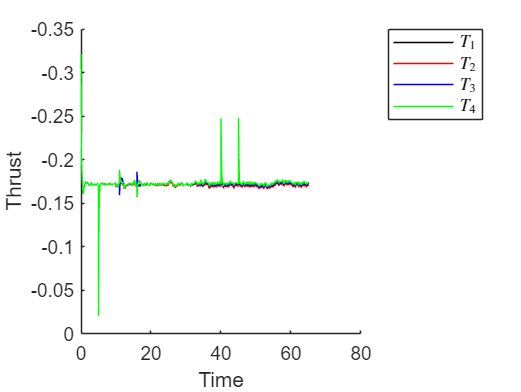

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)
if req_input
input('Press "Enter" to examine the effects of adding feedforward to LQR for position control')
end

Press 'Enter' again to move on to the next section 

close(lqrProj)

## Add a Feedforward term to the LQR Position Controller with Integral Action

The last modification we consider to attempt improving the performance of the controllers is the addition of a feedforward term to modify the reference, as described in Åström and Murray. Show how you compute your feedforward gain.

Ts = 0.005; % Sampling Time

% Initalising the A and B matrix
A0_pf = double(subs(A, [state, control], [zeros(1,12), input_Eq]));
B0_pf = double(subs(B, [state, control], [zeros(1,12), input_Eq]));

% Isolating relevant states: x, y, z and psi
C0_pf = zeros(4,12);
C0_pf(1,1) = 1;
C0_pf(2,2) = 1;
C0_pf(3,3) = 1;
C0_pf(4,6) = 1;

% State Augmentation
A0pi = [A0_pf zeros(12,4); C0_pf zeros(4,4)];
B0pi = [B0_pf; zeros(4,4)];

%dont need for lqrd (only for Q)
C0i = [C0_pf zeros(4,4); zeros(4,12) eye(4)]; % controlling states and integral terms

% Q matrices
Q_diag = diag([0.00003, 0.00003, 0.1, 0.1, 0.00000001, 0.00000001, 0.002, 0.000005]);
Qpif = C0i'*Q_diag*C0i;

R = eye(4);

[K_pif, ~, ~] = lqrd(A0pi, B0pi, Qpif, R, Ts);

Kp_pf = K_pif(:,1:12);

% K_i matrix, needs to be a 4x4 matrix
Ki_pf = zeros(4);
Ki_pf(:,1:3) = K_pif(:,13:15);  % Integral states of x,y,z
Ki_pf(:,4) = K_pif(:,16);       % Integral state of psi

% We want A, B and C to be dimension 4x4
Acontrol_pf = eye(4);
Bcontrol_pf = eye(4)*Ts;
Ccontrol_pf = -Ki_pf;
Dcontrol_pf = zeros(4);

Kcontrol_pf = -Kp_pf;   % Proportional gain

ABK = A0_pf - B0_pf*Kp_pf;

Kr = -inv(C0_pf * inv(ABK) * B0_pf);

Fcontrol_pf = Kr;

% Changes need to be made to the Simulink block as the feedforward and
% feedback gain should be outside the process block.

Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the reference signal gain. Notice the change in control structure from the previous examples to accomodate the added Feedforward term.

if req_input
open_system('LQR_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Then, run the simulation until you are satisfied with the performance of the system. How does the performance differ when compared to the base integral case? How is the controller with feedforward different from the previous controllers you designed?

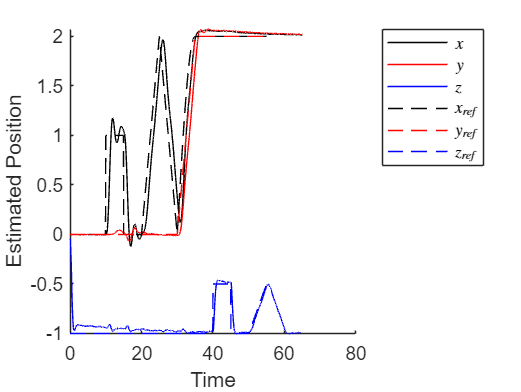

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(13)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

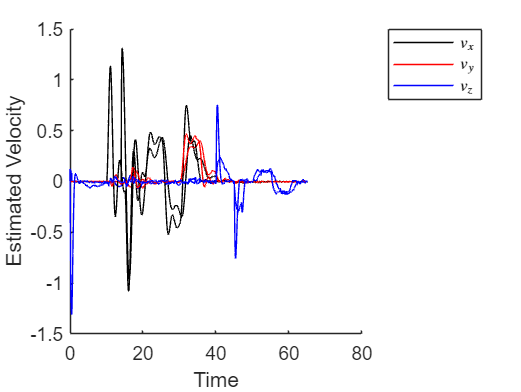

figure(14)
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')

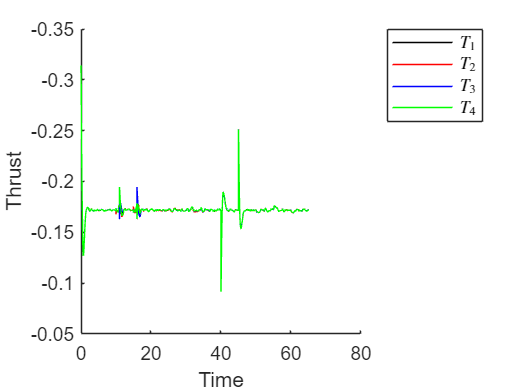

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)
if req_input
input('Press "Enter" to move on to LQR velocity control with feedforward')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add a Feedforward term to the LQR Velocity Controller with Integral Action

Finally, repeat the design of a feedforward term for the velocity controller. Once again, include both the feedforward and integral terms.

% Sampling Time
Ts = 0.005;

% Initalising the A and B matrix
A0_vf = double(subs(A, [state, control], [zeros(1,12), input_Eq])); 
B0_vf = double(subs(B, [state, control], [zeros(1,12), input_Eq]));

% Ignoring positional states
A0_vf = A0_vf(4:end,4:end);
B0_vf = B0_vf(4:end,:);

% Isolating relevant states: v_x, v_y, v_z and psi
C0_vf = zeros(4,12);
C0_vf(1,6) = 1;
C0_vf(2,7) = 1;
C0_vf(3,8) = 1;
C0_vf(4,9) = 1;
C0_vf = C0_vf(:,4:end); % Ignoring Positional States

% State Augmentation
A0i = [A0_vf zeros(9,4); C0_vf zeros(4,4)];
B0i = [B0_vf; zeros(4,4)];

% C0i includes integral terms, (the 4 extra 'integral' states)
C0i = zeros(8,13);
C0i(1,3) = 1;
C0i(2,4) = 1;
C0i(3,5) = 1;
C0i(4,6) = 1;
C0i(5,10) = 1;
C0i(6,11) = 1;
C0i(7,12) = 1;
C0i(8,13) = 1;

% Q Matrices
Q1vif = [0.08 0.00001 0.00001 0.075]; % yaw u v w
Q2vif = [0.0002 0.000005 0.000005 0.08]; % last 4 for integral terms
Qvif = diag([Q1vif Q2vif]);
Qvif = C0i' * Qvif * C0i;

% R Matrix
R = eye(4);

[K_velf0, ~, ~] = lqrd(A0i, B0i, Qvif, R, Ts);

Kp_vf = zeros(4,12);
Kp_vf(:,4:12) = K_velf0(:,1:9);

% Resizing Matrices for 4x4
Ki_vf = K_velf0(:,10:13);
Acontrol_vf = eye(4);
Bcontrol_vf = eye(4)*Ts;
Ccontrol_vf = -Ki_vf;
Dcontrol_vf = zeros(4);

Kcontrol_vf = -Kp_vf;       % Proportional Gain

ABK = A0_vf - B0_vf * Kp_vf(:,4:12);        % Making the dimensions agree (ignoring positional)

Kr = -inv(C0_vf * inv(ABK) * B0_vf);

Fcontrol_vf = Kr;


Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the matrix multiplying the reference signal.

if req_input
open_system('LQR_vel_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of your controller.

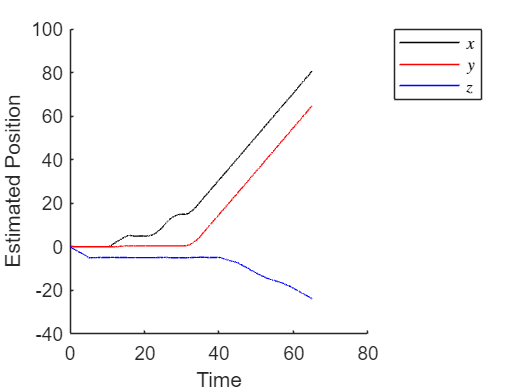

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(15)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

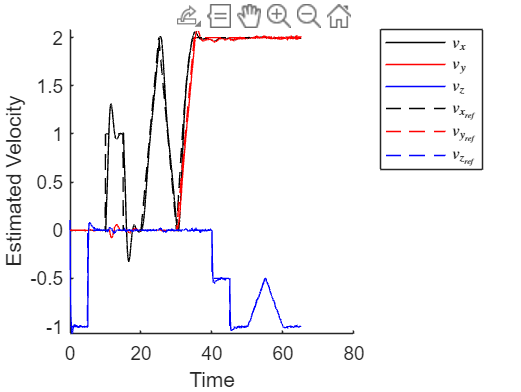

figure(16)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,7),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,8),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,9),'b')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,1),'k--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,2),'r--')
plot(cmds.ans.Time(1:11000),cmds.ans.Data(1:11000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')

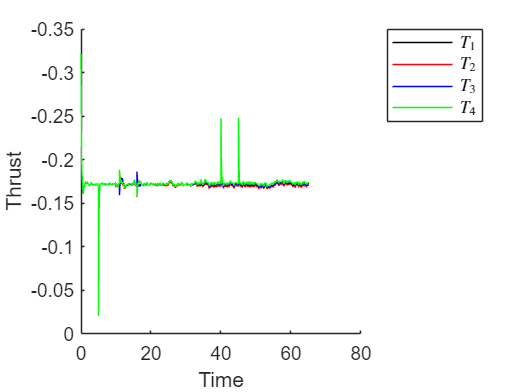

figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,1),'k')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,2),'r')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,3),'b')
plot(simInfo.logsout{13}.Values.Time,simInfo.logsout{13}.Values.Data(:,4),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')

if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

load('robustness_mass_thrust.mat')
%print(SDOSessionData)
sdotool(SDOSessionData)
if req_input
input('Press "Enter" to close the project and terminate the script')
end

Press 'Enter' one last time to terminate the simulation.

close(lqrProj)